# Phys 434 Lab 7

## Natalie Shen

#### Collaborators: Taylor Prewitt, Francesca Bennet

## Event Selection

### Part 1

clear all; close all; clc

h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');


h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


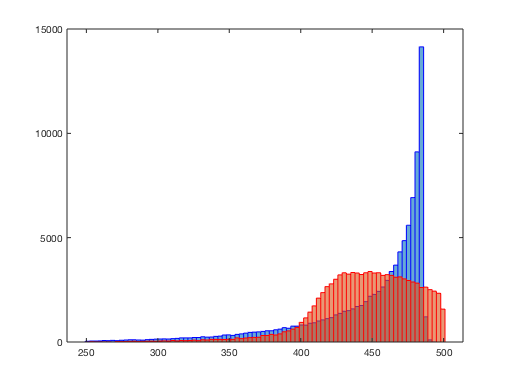

qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

histogram(higg(1,:),"BinMethod","auto","EdgeColor","b")
hold on
histogram(qcd(1,:),"BinMethod","auto","EdgeColor","r")
hold off

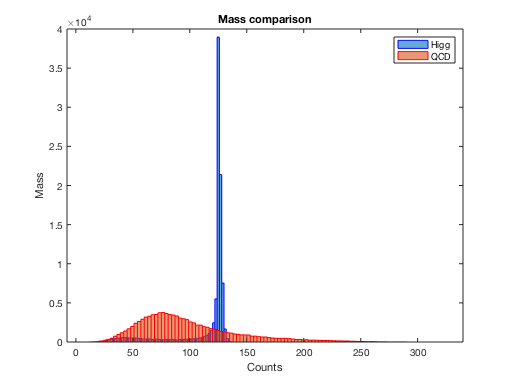


histogram(higg(4,:),"BinMethod","auto","EdgeColor","b")
hold on
histogram(qcd(4,:),"BinMethod","auto","EdgeColor","r")
hold off
title('Mass comparison')
xlabel('Counts')
ylabel('Mass')
legend("show","Higg","QCD")

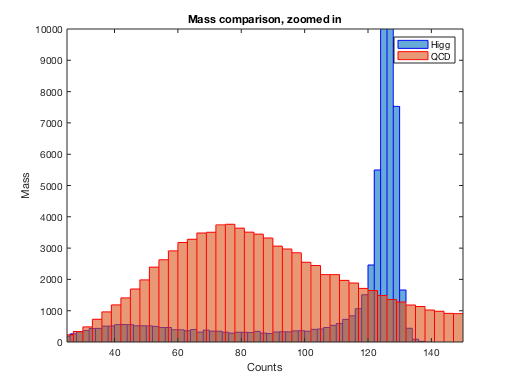


histogram(higg(4,:),"BinMethod","auto","EdgeColor","b")
hold on
histogram(qcd(4,:),"BinMethod","auto","EdgeColor","r")
hold off
xlim([25,150])
ylim([0,10000])
title('Mass comparison, zoomed in')
xlabel('Counts')
ylabel('Mass')
legend("show","Higg","QCD")


higgf=fitdist(higg(4,:)',"Poisson");
qcdf=fitdist(qcd(4,:)',"Poisson");
higgm=mean(higgf);
qcdm=mean(qcdf);

### Part 2

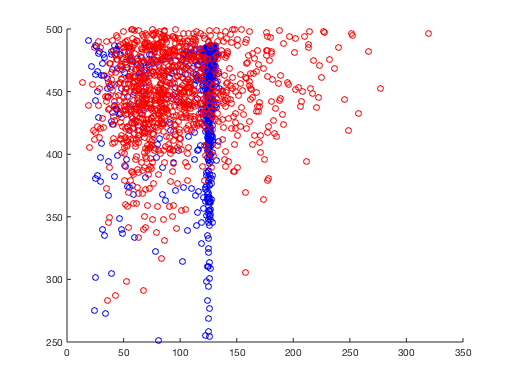

scatter(higg(4,1:100:end),higg(1,1:100:end),"blue");
hold on
scatter(qcd(4,1:100:end),qcd(1,1:100:end),"red");
hold off

# Phys 434 Lab 8

h5disp("data_highLumi_pt_250_500.h5");

HDF5 data_highLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes

higha0 = h5read("data_highLumi_pt_250_500.h5","/data/axis0");
higha1 = h5read("data_highLumi_pt_250_500.h5","/data/axis1");
highitems = h5read("data_highLumi_pt_250_500.h5","/data/block0_items");
highval = h5read("data_highLumi_pt_250_500.h5","/data/block0_values");
h5disp("data_lowLumi_pt_250_500.h5");

HDF5 data_lowLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes:

lowa0 = h5read("data_lowLumi_pt_250_500.h5","/data/axis0");
lowa1 = h5read("data_lowLumi_pt_250_500.h5","/data/axis1");
lowitems = h5read("data_lowLumi_pt_250_500.h5","/data/block0_items");
lowval = h5read("data_lowLumi_pt_250_500.h5","/data/block0_values");